# Report of lunar lander stablization

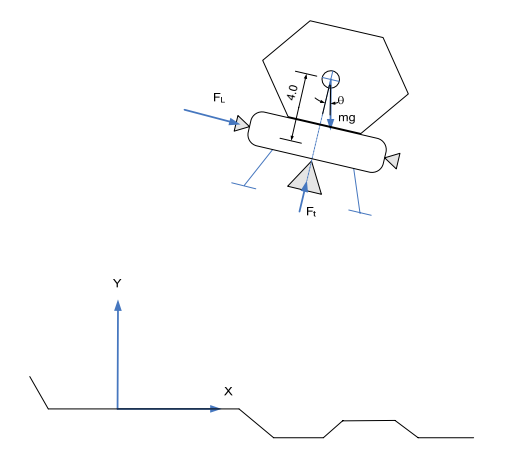

The physical parameters of the system are given as: 

m = 20000; % mass - [kg]
J = 100000; % Moment of Inertia - [kg*m^2]
g = 1.6; % Gravitational Constant - [m/s^2]
L = 4; % length between the gravity center and the bottom of the lander [m]

## 1 System dynamics

The nonlinear state-space model of the dynamics of the lander is constracted as:


$$\ddot{x} = \frac{1}{m} F_l \cos{\theta} + \frac{1}{m} F_t \sin{\theta}\\
\ddot{y}=-\frac{1}{m} F_l \sin{\theta} + \frac{1}{m} F_t \cos{\theta} - g\\
\ddot{\theta} = \frac{L}{J}F_l$$


Let $X = [x , y ,\theta ,\dot{x} ,\dot{y} ,\dot{ \theta}] ˆ T$,$U=[F_l,F_t]^T$,

M = diag([m,m,J]);
dx = @(x,u) [x(4:6); 
            u(1)*cos(x(3))/m + u(2)*sin(x(3))/m;
            -u(1)*sin(x(3))/m + u(2)*cos(x(3))/m;
            L/J*u(1)];

## 2 Linearization of the system

Approximate the system dynamic using Taylor series:


$$m\ddot{x} = f_1 = (-F_l^* \sin{\theta ^*}+ F_t^* \cos{\theta^*})\theta + \cos{\theta^*}F_l + \sin{\theta^*}F_t + \theta^*F_l^*\sin{\theta^*}-\theta^*F_t^*\cos{\theta^*}$$



$$m\ddot{y} = f_2 = (-F_l^* \cos{\theta ^*}- F_t^* \sin{\theta^*})\theta - \sin{\theta^*}F_l + \cos{\theta^*}F_t + \theta^*F_l^*\cos{\theta^*} + \theta^*F_t^*\sin{\theta^*} - mg$$


The nonlinear system can be approximately expressed as:

 
$$\dot{X} =\left[ \matrix{
0& 0& 0& 1& 0& 0 \cr
0& 0& 0& 0& 1& 0 \cr
0& 0& 0& 0& 0& 1 \cr
0& 0& \frac{a_1}{m}& 0& 0& 0 \cr
0& 0& \frac{a_2}{m}& 0& 0& 0\cr
0& 0& 0& 0& 0& 0\cr
}\right]X+\left[ \matrix{
0 & 0 \cr
0 & 0 \cr
0 & 0 \cr
\frac{\cos{\theta^*}}{m} & \frac{\sin{\theta^*}}{m} \cr
\frac{-\sin{\theta^*}}{m} & \frac{\cos{\theta^*}}{m} \cr
\frac{L}{J} & 0 
} \right] U$$


where $a_1=-F_l^* \sin{\theta ^*}+ F_t^* \cos{\theta^*}$, $a_2 = -F_l^* \cos{\theta ^*}- F_t^* \sin{\theta^*}$.

It's easy to obtain the trim point of the system:


$$X^* = [0,0,0,0,0,0]^T$$



$$U^* = [0,g]^T$$


And the linearized state-space system model is:


$$\dot{X} =\left[ \matrix{
0& 0& 0& 1& 0& 0 \cr
0& 0& 0& 0& 1& 0 \cr
0& 0& 0& 0& 0& 1 \cr
0& 0& \frac{g}{m}& 0& 0& 0 \cr
0& 0& 0& 0& 0& 0\cr
0& 0& 0& 0& 0& 0\cr
}\right]X+\left[ \matrix{
0 & 0 \cr
0 & 0 \cr
0 & 0 \cr
\frac{1}{m} & 0 \cr
\frac{0}{m} & \frac{1}{m} \cr
\frac{L}{J} & 0 
} \right] U$$



O = zeros(3,3); 
I = eye(3,3);
T = [1/m 0 L/J; 0 1/m 0]';
N = O;
N(1,3) = g/m;
A = [O, I; N, O];
B = [zeros(3,2); T];

## 3 Stablization of the lunar lander using LQR

Choose the weight matrix as follows, and generate the LQR gain matrix:

Q = 1*diag([1 .01 1 1 1 1]);
R = 0.1*diag([.1 1]);
K = lqr(A,B,Q,R); % LQR gain

Then, set the simulation parameters as:

h = 0.1; % sampling intervel
tspan = 10000; % simulation time span
simtime = 0:h:tspan; % simulation time serie
nmax = length(simtime); % simulation step
% x0 = [-2 2 pi/2 0.1 0 0]'; % initial condition 1
x0 = [-20 20 0 0.1 2 0]'; % initial condition 2
r = [0 0 0 0 0 0]'; % reference points


Actuator and system states have constraints: 

Umax = [0.5e3,44e3]'; % maximum actuator effort
Umin = [-0.5e3,-m*g]'; % minimum actuator effort
dXmax = [1, .1, pi/6, 1, .1, pi/24]';  % maximum increment of states
Xmax = [1000,1000, pi/2, 100, 100, pi/20]'; % maximum states
Xmin = [-1000, 0, -pi/2, -100, -100, -pi/20]'; % minimum states


##  3.1 simulation with linearized system

With the generated LQR gain, we can perform the close loop simulation of the linearized sytem:

U = zeros(2,nmax);
X = zeros(6,nmax); 
X(:,1) = x0; 
for n = 2:nmax
	U(:,n-1) = max(min(K*(r-X(:,n-1)),Umax),Umin);
    X_dot = min(A*X(:,n-1) + B*U(:,n-1),dXmax);
    X(:,n) = max(min( X(:,n-1) + h*X_dot, Xmax),Xmin);
end

Plot the results:

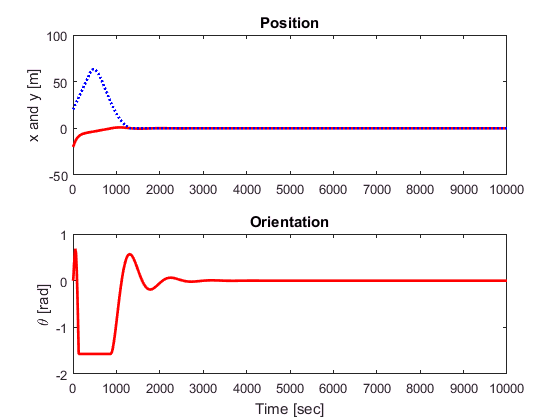

figure
subplot(2,1,1)
plot(simtime,X(1,:),'r-','Linewidth',2);
hold on 
plot(simtime,X(2,:),'b:','Linewidth',2);
ylabel('x and y [m]')
title('Position');
hold off
subplot(2,1,2)
plot(simtime,X(3,:),'r-','Linewidth',2);
ylabel('\theta [rad]');
xlabel('Time [sec]');
title('Orientation');

**        Figure. 1 The position of orientation via linearized system.**

Choose a different set of weight matrix as follows, and generate the LQR gain matrix:

Q = 100*diag([1 .01 1 1 1 1]);
R = 0.1*diag([.1 1]);
K = lqr(A,B,Q,R); % LQR gain
U = zeros(2,nmax);
X = zeros(6,nmax); 
X(:,1) = x0; 
for n = 2:nmax
	U(:,n-1) = max(min(K*(r-X(:,n-1)),Umax),Umin);
    X_dot = min(A*X(:,n-1) + B*U(:,n-1),dXmax);
    X(:,n) = max(min( X(:,n-1) + h*X_dot, Xmax),Xmin);
end

Plot the results:

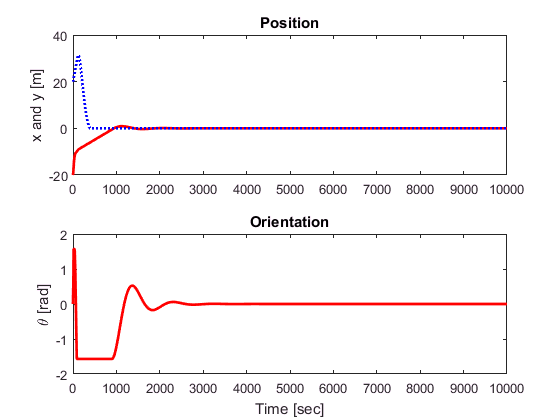

figure
subplot(2,1,1)
plot(simtime,X(1,:),'r-','Linewidth',2);
hold on 
plot(simtime,X(2,:),'b:','Linewidth',2);
ylabel('x and y [m]')
title('Position');
hold off
subplot(2,1,2)
plot(simtime,X(3,:),'r-','Linewidth',2);
ylabel('\theta [rad]');
xlabel('Time [sec]');
title('Orientation');

**        Figure. 2 The position of orientation via linearized system.**

As is shown in the figure, the curves converge faster when adopting a larger weighting matrix.

## 3.2 simulation with nonlinear system

Using the achieved LQR gains for the linear system, the simulation of the nonlinear sytem is performed as follows:

Q = 1*diag([1 .01 1 1 1 1]);
R = 0.1*diag([.1 1]);
K = lqr(A,B,Q,R); % LQR gain
Un = zeros(2,nmax);
Xn = zeros(6,nmax); 
Xn(:,1) = x0; 
for n = 2:nmax
	Un(:,n-1) = max(min(K*(r-Xn(:,n-1)), Umax),Umin);
    X_dot = min(dx(Xn(:,n-1),Un(:,n-1)),dXmax);
    Xn(:,n) = max(min( Xn(:,n-1) + h*X_dot, Xmax),Xmin);
end

Plot the results:

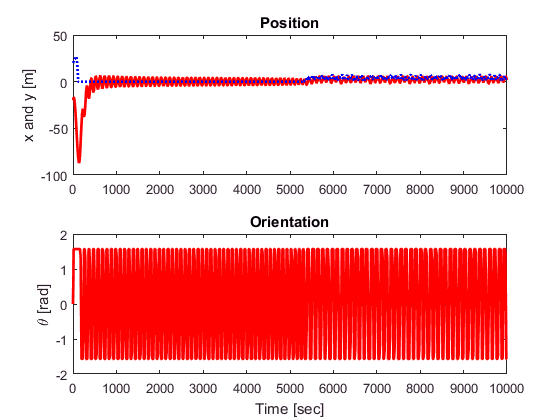

figure
subplot(2,1,1)
plot(simtime,Xn(1,:),'r-','Linewidth',2);
hold on 
plot(simtime,Xn(2,:),'b:','Linewidth',2);
ylabel('x and y [m]')
title('Position');
hold off
subplot(2,1,2)
plot(simtime,Xn(3,:),'r-','Linewidth',2);
ylabel('\theta [rad]');
xlabel('Time [sec]');
title('Orientation');

**        Figure. 3 The position of orientation via nonlinear system with LQR gain.**

## 3.3 Discussion

Observing Figure. 1, the lunar lander is succesfully stablized using the generated LQR gain. Howerver, the LQR gain for linear system seems not suitable for the nonlinear one. Althogh the signals are shacking aroud the reference points, the nonlinear system is still not stable.